Q=0.00009651

Q = 9.6510e-05

n=0.75

n = 0.7500

C=0.00000651

C = 6.5100e-06

r=143

r = 143

t=1

t = 1

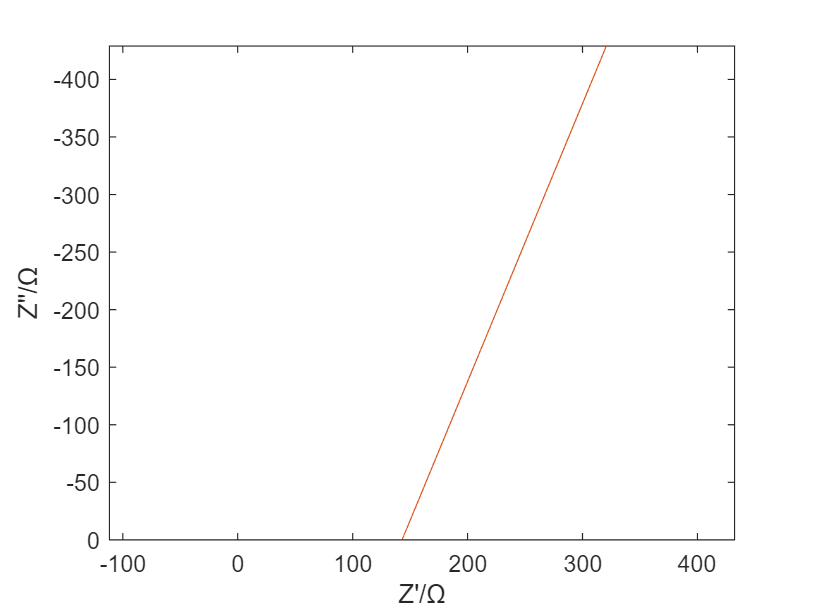


data_sample=data_20190620_ppal_0(1:2,:);
data_sample(2,:)=data_20190620_ppal_0((t+1),:);
f=data_sample(1,:);
Zcpe=1./((2j*pi.*f).^n.*Q)+r;
Zc=1./((2j*pi.*f).*C);
data_cpe=data_sample;
data_cpe(2,:)=Zcpe;
Zres=sub_sys(data_sample,data_cpe);
Zres(2,:)=Zres(2,:);
% Zres(2,:)=1./(1./Zres(2,:)-1/r)
figure()
plotcplx_all_test(data_sample)
hold on
plotcplx_all_test(data_cpe)

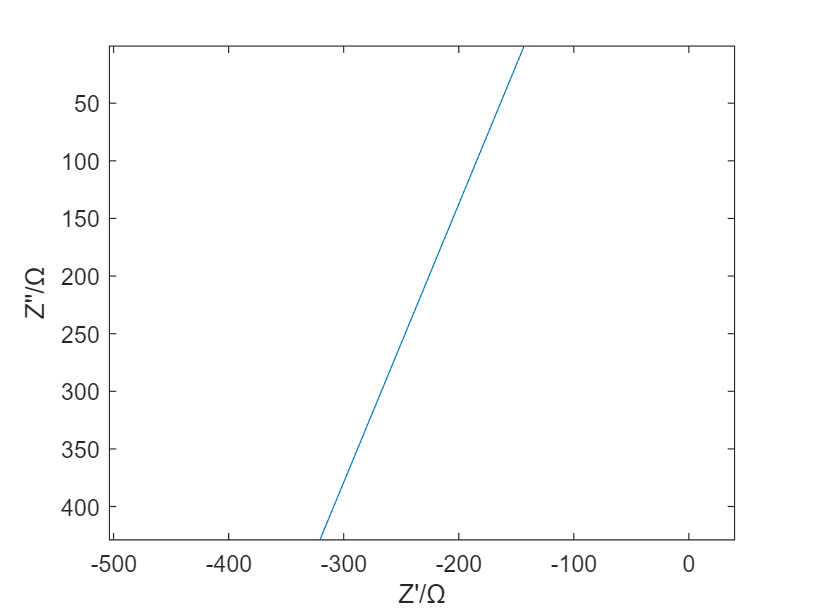

figure()
plotcplx_all_test(Zres)

% figure()
% plotang_all(data_sample)
% figure()
% plotecplx_all(data_sample)